# Part 1: 電力系統の作成と機器の種類

電力系統のモデルを、母線・ブランチ・機器・制御器の 4 つの部品で組み立てます。小さな系統を自分で組み立てたあと、同梱の IEEE 9 母線系統を使って、単位法、送電線と変圧器の等価回路、アドミタンス行列 $I = YV$、母線の種類、発電機の動揺方程式、負荷モデル、制御器を、数式と計算で一つずつ確かめます。

**この Part で分かること**

- 電力系統のモデルをつくる 4 つの部品と、GUILDA での組み立て方

- 値を単位法で表す理由と、送電線（π 型等価回路）と変圧器を回路として表す方法

- ブランチをまとめた母線アドミタンス行列 $I = YV$ と、それが疎行列になる理由

- 3 つの母線の種類（Slack・PV・PQ）と、それぞれがあらかじめ決める量

- 発電機・負荷・制御器のモデルと、その詳しさの段階。同梱のベンチマーク系統

知識ページ: [Part 1: 電力系統の作成と機器の種類](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part1-network-components.html","-browser"))（クリックするとブラウザで開きます）。知識ページの図は、このライブスクリプトを実行すると描けます。

**注意**: 実行する前に、GUILDA のフォルダで `GUILDA` を実行してパスを通しておきます。上のリンクも、このパスから知識ページの場所を求めて開きます。全体の実行には 1〜2 分かかります。

## 0. 図の色

この Part の図は、知識ページと同じ配色で描きます。色を RGB（0〜1）で決めておきます。

sct_color.rr_brand = [0, 89, 167] / 255;    % 青: 主役の量
sct_color.rr_c2    = [46, 107, 63] / 255;   % 緑
sct_color.rr_c3    = [154, 91, 0] / 255;    % 橙: 比べる相手
sct_color.rr_muted = [90, 101, 112] / 255;  % 灰色: 補助の線

## 1. 系統をつくる 4 つの部品

実際の電力系統には数え切れないほどの設備がありますが、解析のためには 4 種類の部品に分けて考えれば十分です。

- **母線**: 変電所などの、送電網の接続点です。母線ごとに 1 つの電圧（大きさと位相角）を持ちます。

- **ブランチ**: 2 つの母線を結ぶ送電線や変圧器です。

- **機器**: 母線につながり、送電網に電力を送り込む、または取り出す設備です。発電機と負荷がこれにあたります。

- **制御器**: 機器の状態を測り、その入力を調整する装置です。1 つの機器に属するローカル制御器と、系統全体に属するグローバル制御器があります。

部品は階層になっています。GUILDA では系統が `PowerNetwork` のオブジェクトで、母線・ブランチ・グローバル制御器を持ちます。母線はそこにつながる機器を持ち、機器はそのローカル制御器を持ちます。この順に、3 母線の小さな系統を組み立てます。

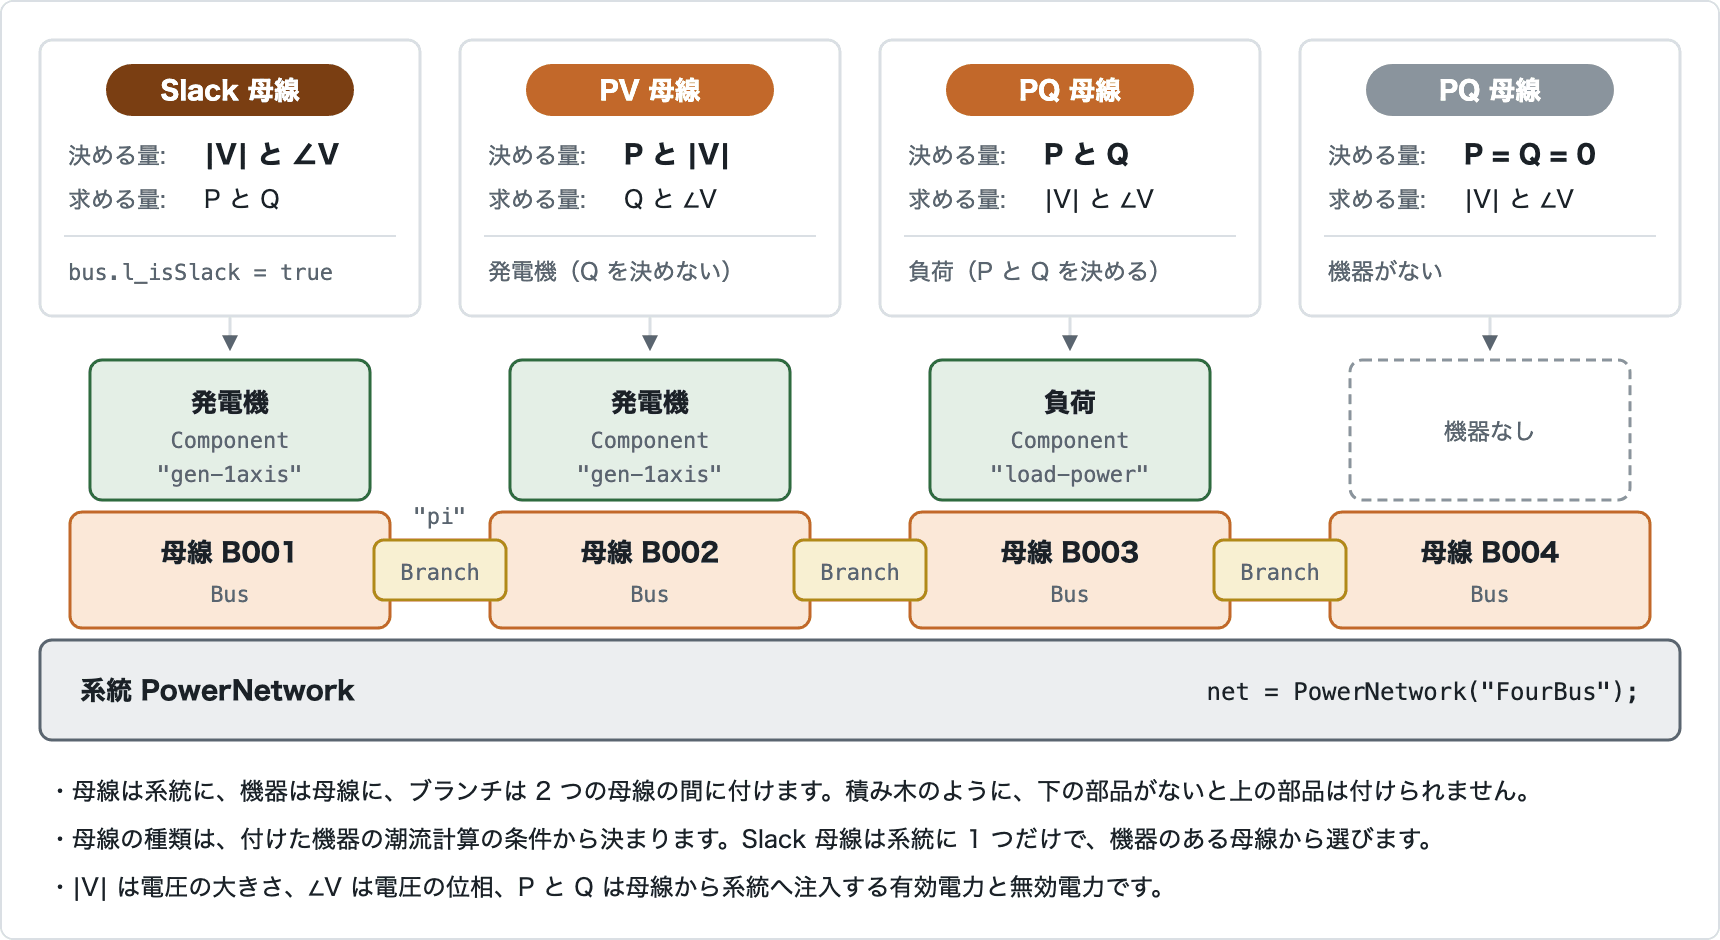

図は、母線・ブランチ・機器を積み木のように系統に積み上げた 4 母線の一例です。下の部品がないと上の部品は付けられません。上の段は、つながった機器によって決まる母線の種類です（5 節）。この Part では、機器のない母線を除いた 3 母線の系統を組み立てます。

### 1.1 空の系統と母線

`PowerNetwork` で母線を 1 つも持たない空の系統をつくり、`add_bus` で母線を 3 つ加えます。`X` と `Y` は系統図に描くときの位置です。

net = PowerNetwork("ThreeBus");
net.add_bus(V=1.0, Varg=0, X=0, Y=0);
net.add_bus(V=1.0,         X=1, Y=0);
net.add_bus(               X=2, Y=0);
net.tab_parameter

ans = table
        base     
    _____________

    Hz    baseMVA
    __    _______
                 
    60      100  


系統が持つパラメータは、定格周波数 `Hz` と、単位法の基準電力 `baseMVA`（MVA）です。以後の電気の量は、すべてこの基準電力についての単位法の値で与えます（2 節）。母線には、加えた順に `B001`、`B002`、`B003` のタグが付きます。

**注意**: `V`（pu）と `Varg`（rad）は、その母線が Slack 母線や PV 母線になったときの電圧の設定値です。PQ 母線では使われません。

### 1.2 ブランチと機器

`add_branch` で母線 1–2 と母線 2–3 を送電線（π 型等価回路、Key は `"pi"`）でつなぎ、母線 1 と 2 に発電機（1 軸モデル `"gen-1axis"`）を、母線 3 に定電力負荷 `"load-power"` をつなぎます。

net.add_branch("pi", [1,2], R=0.010, X=0.085, C=0.088);
net.add_branch("pi", [2,3], R=0.017, X=0.092, C=0.079);
net.a_Bus{1}.add_component("gen-1axis",  P=0.0);
net.a_Bus{2}.add_component("gen-1axis",  P=0.5);
net.a_Bus{3}.add_component("load-power", P=-0.5, Q=-0.1);

`R`・`X` は直列の抵抗とリアクタンス、`C` は片端ぶんの対地サセプタンスで、どれも単位法の値です（3 節）。機器の `P`・`Q` は、潮流計算で使う、機器が送電網へ送り込む電力の設定値です。負荷は電力を取り出すので負の値にします。

### 1.3 Slack 母線を決めて確かめる

GUILDA は Slack 母線を自動では選びません。母線 1 を Slack 母線にし、母線の種類の表、部品の階層、系統図で確かめます。

net.a_Bus{1}.l_isSlack = true;

INFO: ' B001 '  set as slack bus.
      P and Q specifications for ' B001SG1 ' ignored in powerflow calculation.


net.get_pf_condition();

Bus
             Type      Varg     V      P       Q  
            _______    ____    ___    ____    ____

    B001    "slack"      0       1     NaN     NaN
    B002    "PV"       NaN       1     0.5     NaN
    B003    "PQ"       NaN     NaN    -0.5    -0.1



net.disp_tree();


 ThreeBus @PowerNetwork
   ┣━━ B001 @Bus
   ┃     ┗━━ B001SG1 @component.generator.one_axis
   ┃          ┣━━ B001SG1CA1 @controller.avr.Static
   ┃          ┗━━ B001SG1CG1 @controller.governor.Static
   ┣━━ B002 @Bus
   ┃     ┗━━ B002SG1 @component.generator.one_axis
   ┃          ┣━━ B002SG1CA1 @controller.avr.Static
   ┃          ┗━━ B002SG1CG1 @controller.governor.Static
   ┣━━ B003 

INFO: net.plot_diagram: 'ThreeBus' is not initialized or not up to date, so the diagram shows the topology only. Run net.initialize() and draw again for the equilibrium.


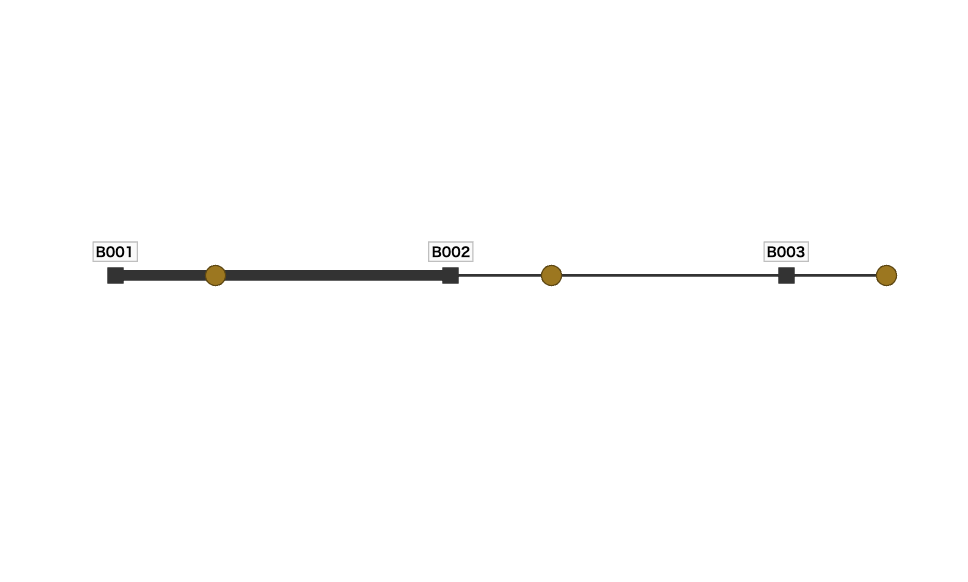

G = net.plot_diagram();

表の `Type` が母線の種類です（5 節）。Slack 母線に指定した B001 は slack、発電機のある B002 は PV、負荷だけの B003 は PQ になりました。`NaN` の欄は、潮流計算で求める量です。階層の表示では、機器が母線の下に、ブランチが系統の直下に並びます。発電機の下には、既定で入力を一定に保つ静的な AVR とガバナ（`avr.Static`、`governor.Static`）が付いています。制御器を付けると、これと置き換わります（8 節）。まだ潮流計算をしていないので、系統図にはつながりだけが描かれます。

**注意**: ブランチの種類と Key は `GUILDA.dictionary("Branch")` で一覧できます。`net.initialize()` で平衡点を求めると、系統図に電流などの値が色で描かれます（潮流計算は Part 2 で扱います）。

## 2. 単位法

1 つの系統の中には、数百 kV から数 kV までの電圧と、数 MW から数千 MW までの電力が混ざっています。比べやすくするため、それぞれの量を決めておいた基準値 $x_\mathrm{base}$ で割って表します。これを**単位法**（per unit、pu）といいます。


$$x_\mathrm{pu} = \frac{x}{x_\mathrm{base}}$$


基準の電力 $S_\mathrm{base}$（三相分）は系統全体で 1 つ、基準の電圧 $V_\mathrm{base}$（線間電圧）は電圧の階級ごとに、ふつうはその定格電圧に決めます。基準の電流と基準のインピーダンスは、この 2 つから決まります。


$$I_\mathrm{base} = \frac{S_\mathrm{base}}{\sqrt{3}\,V_\mathrm{base}}, \qquad Z_\mathrm{base} = \frac{V_\mathrm{base}}{\sqrt{3}\,I_\mathrm{base}} = \frac{V_\mathrm{base}^2}{S_\mathrm{base}}$$


3 つの電圧階級（500 kV、66 kV、6.6 kV）の母線電圧を、実際の値と単位法の値で比べます。

rr_base = [500, 66, 6.6];      % [kV] 基準電圧（各階級の定格電圧）
rr_V = [495, 67.3, 6.6];       % [kV] 母線電圧
rr_pu = rr_V ./ rr_base        % [pu]

rr_pu =     0.9900    1.0197    1.0000


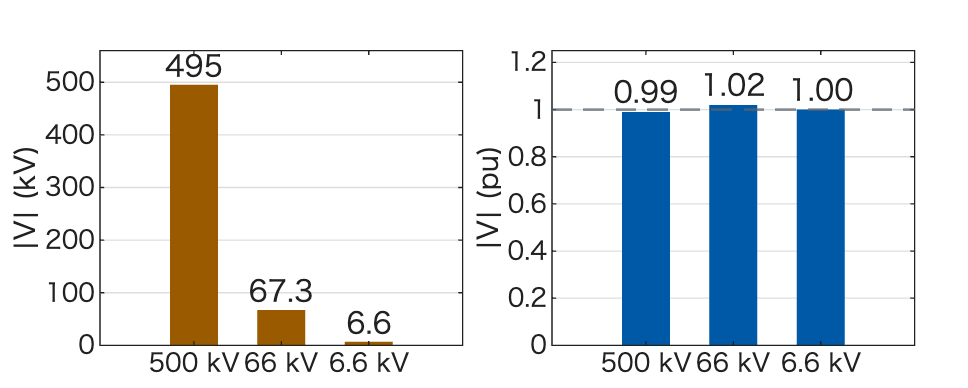

sr_level = ["500 kV", "66 kV", "6.6 kV"];

figure(Position=[100, 100, 900, 360]);
tl = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
ax = nexttile(tl);
bar(ax, 1:3, rr_V, 0.55, FaceColor=sct_color.rr_c3, EdgeColor="none");
set(ax, XTick=1:3, XTickLabel=sr_level, YLim=[0, 560], YGrid="on", Box="on");
ylabel(ax, "|V| (kV)");
text(ax, 1:3, rr_V + 8, compose("%.4g", rr_V), HorizontalAlignment="center", VerticalAlignment="bottom");
ax = nexttile(tl);
bar(ax, 1:3, rr_pu, 0.55, FaceColor=sct_color.rr_brand, EdgeColor="none");
yline(ax, 1, "--", Color=sct_color.rr_muted, LineWidth=1);
set(ax, XTick=1:3, XTickLabel=sr_level, YLim=[0, 1.25], YGrid="on", Box="on");
ylabel(ax, "|V| (pu)");
text(ax, 1:3, rr_pu + 0.02, compose("%.2f", rr_pu), HorizontalAlignment="center", VerticalAlignment="bottom");

実際の値（左）では 100 倍近く違いますが、各階級の定格電圧を基準にすると（右）、どれも 1 の近くになります。電圧 0.99 pu なら、どの階級でも「定格より 1 % 低い」という意味です。値を見ただけで正常かどうかが分かるのが、単位法の第一の利点です。

### IEEE 9 母線系統の値を実際の単位に戻す

同梱の IEEE 9 母線系統を読み込み、その基準電力と、送電線の定数を見ます。`get_parameter` は、指定した Key の部品のパラメータを 1 本 1 行の表で返し、`get_element` はタグで部品を取り出します。以下では、母線 4–5 を結ぶ `EL004` を使います。

net9 = network.IEEE9bus(LocalController=true);
r_Sbase = net9.tab_parameter.base.baseMVA     % [MVA] 基準電力

r_Sbase = 100

net9.get_parameter("dynamics", Key="pi")      % 6 本の送電線の定数

ans = 6×6 table
               R         X         C       tap    phase    circuit
             ______    ______    ______    ___    _____    _______

    EL004      0.01     0.085     0.088    NaN     NaN        2   
    EL005     0.017     0.092     0.079    NaN     NaN        2   
    EL006     0.032     0.161     0.153    NaN     NaN        2   
    EL007     0.039      0.17     0.179    NaN     NaN        2   
    EL008    0.0085     0.072    0.0745    NaN     NaN        2   
    EL009    0.0119    0.1008    0.1045    NaN     NaN        2   


br4 = net9.get_element("EL004");

送電線は 230 kV の階級にあります。基準インピーダンス $Z_\mathrm{base} = V_\mathrm{base}^2/S_\mathrm{base}$ を求めて、単位法の $R$・$X$ を Ω に戻します。

r_Vbase = 230;                                % [kV] 230 kV の階級の基準電圧
r_Zbase = r_Vbase^2 / r_Sbase                 % [Ω]

r_Zbase = 529

rr_ohm = [br4.tab_parameter.dynamics.R, br4.tab_parameter.dynamics.X] * r_Zbase   % [Ω] R と X

rr_ohm =     5.2900   44.9650


$X = 0.085$ pu は 45 Ω にあたり、$R$ の 8 倍以上あります。高い電圧の送電線では、電力の流れ方は主にリアクタンスで決まります（Part 2）。もう 1 つの利点は、変圧器から巻数比が消えることです。発電機の母線（16.5 kV など）と 230 kV の母線を結ぶ変圧器も、両側の定格電圧を基準にすれば公称の変圧比は 1 になり、そこからのずれ（タップ）だけが残ります。

**注意**: GUILDA では、電気の量はすべて系統の基準電力についての単位法の値で扱います。IEEE のベンチマーク系統では 100 MVA、電気学会の標準モデルでは 1000 MVA です。時間は秒、角度はラジアンです。

## 3. 送電線と変圧器

送電線は何 km もの電線ですが、商用周波数での解析では **π 型等価回路**に置き換えられます。両端の間に直列インピーダンス $R + jX$ を置き、線路の対地静電容量のサセプタンス $B$ の半分ずつを両端に置きます。直列のアドミタンスを $y = 1/(R + jX)$ とすると、母線 $i$ の端と母線 $j$ の端から線路に流れ込む電流 $I_{ij}$、$I_{ji}$ は、両端の電圧 $V_i$、$V_j$（単位法の複素数のフェーザ）から次のように決まります。


$$\left[\begin{array}{c} I_{ij} \\ I_{ji} \end{array}\right] = \left[\begin{array}{cc} y + j\frac{B}{2} & -y \\ -y & y + j\frac{B}{2} \end{array}\right] \left[\begin{array}{c} V_i \\ V_j \end{array}\right]$$


$y(V_i - V_j)$ は直列インピーダンスを流れる電流、$j(B/2)V_i$ は片端の充電電流です。GUILDA の `pi` ブランチの `C` は、この片端の値 $C = B/2$ です。`EL004` の 2×2 の行列を GUILDA から取り出し、上の式で計算したものと比べます。

cm_Ybr = br4.get_admittance_matrix()

cm_Ybr =    1.3652 -11.5161i  -1.3652 +11.6041i
  -1.3652 +11.6041i   1.3652 -11.5161i


sct_par = br4.tab_parameter.dynamics;
c_y = 1 / (sct_par.R + 1j * sct_par.X);       % 直列のアドミタンス
cm_Yformula = [c_y + 1j * sct_par.C, -c_y; -c_y, c_y + 1j * sct_par.C]

cm_Yformula =    1.3652 -11.5161i  -1.3652 +11.6041i
  -1.3652 +11.6041i   1.3652 -11.5161i


max(abs(cm_Ybr - cm_Yformula), [], "all")

ans = 0

2 つの行列は一致します（差は計算の丸めの大きさです）。非対角の $-y$ の実部が正、虚部が正になるのは、$X$ が $R$ より大きく $y \approx -j/X$ だからです。

**変圧器**は、単位法で表すと、タップ比 $t$ の理想変圧器と、直列の漏れリアクタンスをつないだものになります。GUILDA の `pi_transformer`（位相のずれが 0 のとき）は、理想変圧器を母線 $i$ の側に置いた次の行列です。$t = 1$ なら送電線と同じ形になり、$t \ne 1$ では両端の対角要素が $1/t^2$ だけ違います。タップを変えると片側の電圧が上がったり下がったりするので、電圧を範囲内に保つ手段の 1 つになります。


$$\left[\begin{array}{c} I_{ij} \\ I_{ji} \end{array}\right] = \left[\begin{array}{cc} \left(y + jC\right)/t^2 & -y/t \\ -y/t & y + jC \end{array}\right] \left[\begin{array}{c} V_i \\ V_j \end{array}\right]$$


IEEE 9 母線系統の 3 台の変圧器（発電機の母線と 230 kV の母線を結ぶもの）の定数を見ます。

net9.get_parameter("dynamics", Key="pi_transformer")

ans = 3×6 table
             R      X       C    tap    phase    circuit
             _    ______    _    ___    _____    _______

    ET001    0    0.0576    0     1       0         2   
    ET002    0    0.0625    0     1       0         2   
    ET003    0    0.0586    0     1       0         2   


どれも抵抗と対地容量は 0 で、漏れリアクタンス（`ET001` なら 0.0576 pu）だけの変圧器です。タップ比 `tap` は 1、位相のずれ `phase` は 0 です。

**注意**: GUILDA のブランチは `pi`、`T`（対地静電容量を中央に置く送電線）、`pi_transformer`、`two_winding_transformer` の 4 種類です。変圧器の 2 種類は、`add_branch` の `Tap` と `Phase` でタップ比と位相のずれを指定できます。値は全回線の合計で、回線数 `Circuit` の既定値は 2 です。

## 4. アドミタンス行列：I = YV

ブランチをつなぎ合わせると、系統全体になります。母線 $i$ の機器が送電網に注入する電流 $I_i$ は、その母線につながるブランチへ流れ出ます（キルヒホッフの電流則）。3 節のブランチの行列を使うと、母線ごとに 1 本の線形の式になります。


$$I_i = \sum_{j=1}^{n} Y_{ij} V_j \quad (i = 1, \dots, n) \qquad \Longleftrightarrow \qquad I = YV$$


$n$ は母線の数、$Y$ は**母線アドミタンス行列**です。π 型の送電線だけの系統では、母線 $i$ と $k$ を結ぶ線路の直列アドミタンスを $y_{ik}$、サセプタンスを $B_{ik}$、母線 $i$ の並列アドミタンスを $y_{\mathrm{sh},i}$ とすると、要素は次のようになります。


$$Y_{ii} = \sum_{k \in \mathcal{N}_i} \left( y_{ik} + j\frac{B_{ik}}{2} \right) + y_{\mathrm{sh},i}, \qquad Y_{ik} = -y_{ik} \quad (k \in \mathcal{N}_i)$$


$\mathcal{N}_i$ は母線 $i$ と送電線でつながる母線の集合で、それ以外の $k \ne i$ では $Y_{ik} = 0$ です。一般には、変圧器も含めて、ブランチごとに自分の 2×2 の行列を行と列 $i$、$j$ の位置に足し込みます。IEEE 9 母線系統で、この足し込みを自分で行い、GUILDA の `get_admittance_matrix` の結果と比べます。

cm_Y = net9.get_admittance_matrix().Variables;     % GUILDA が組み立てた Y（9×9）
n_bus = size(cm_Y, 1);
sv_bus = net9.get_element_table(Kind="bus").Tag;     % 母線のタグ（Y の行と列の順）
tab_br = net9.get_element_table(Kind="branch");     % ブランチのタグと両端の母線（From、To）
tab_br(:, ["Key", "From", "To"])

ans = 9×3 table
                   Key            From       To  
             ________________    ______    ______

    ET001    "pi_transformer"    "B001"    "B004"
    ET002    "pi_transformer"    "B002"    "B007"
    ET003    "pi_transformer"    "B003"    "B009"
    EL004    "pi"                "B004"    "B005"
    EL005    "pi"                "B004"    "B006"
    EL006    "pi"                "B005"    "B007"
    EL007    "pi"                "B006"    "B009"
    EL008    "pi"                "B007"    "B008"
    EL009    "pi"                "B008"    "B009"


cm_Ysum = zeros(n_bus);
for i_br = 1:height(tab_br)
    iv_end = [find(sv_bus == tab_br.From(i_br)), find(sv_bus == tab_br.To(i_br))];   % 両端の母線の番号
    br = net9.get_element(tab_br.Tag(i_br));
    cm_Ysum(iv_end, iv_end) = cm_Ysum(iv_end, iv_end) + br.get_admittance_matrix();
end
max(abs(cm_Y - cm_Ysum), [], "all")

ans = 0

ブランチの行列を足し込んだだけで、GUILDA の $Y$ と一致しました（この系統には母線の並列素子がありません）。0 でない要素の位置を図にします。

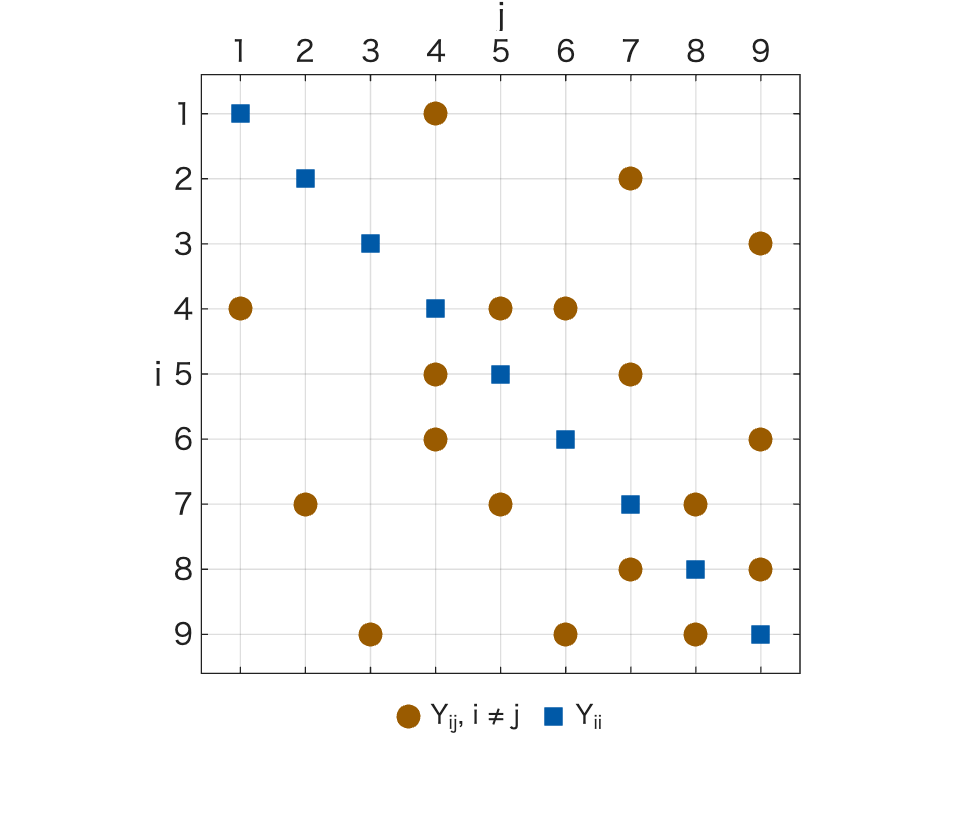

[iv_row, iv_col] = find(abs(cm_Y) > 0);
lv_diag = iv_row == iv_col;
figure(Position=[100, 100, 520, 440]);
ax = axes(Box="on", XGrid="on", YGrid="on");
hold(ax, "on");
plot(ax, iv_col(~lv_diag), iv_row(~lv_diag), "o", MarkerSize=8, LineWidth=1, ...
    MarkerFaceColor=sct_color.rr_c3, MarkerEdgeColor=sct_color.rr_c3, DisplayName="Y_{ij}, i ≠ j");
plot(ax, iv_col(lv_diag), iv_row(lv_diag), "s", MarkerSize=8, LineWidth=1, ...
    MarkerFaceColor=sct_color.rr_brand, MarkerEdgeColor=sct_color.rr_brand, DisplayName="Y_{ii}");
set(ax, YDir="reverse", XLim=[0.4, n_bus + 0.6], YLim=[0.4, n_bus + 0.6], XTick=1:n_bus, ...
    YTick=1:n_bus, XAxisLocation="top", DataAspectRatio=[1, 1, 1]);
xlabel(ax, "j");
ylabel(ax, "i", Rotation=0, VerticalAlignment="middle", HorizontalAlignment="right");
legend(ax, Location="southoutside", Orientation="horizontal", Box="off");

fprintf("0 でない要素: %d 個（全 %d 個）\n", nnz(abs(cm_Y) > 0), numel(cm_Y));

0 でない要素: 27 個（全 81 個）


ブランチ 1 本ごとに、非対角の要素 $Y_{ij} = Y_{ji}$ が 1 組できます。9 本のブランチから 18 個、対角の 9 個と合わせて、81 個の要素のうち 0 でないのは 27 個だけです。1 つの母線がつながる母線は数本しかないので、母線が増えるほど 0 の割合が増えます。このような行列を**疎行列**といいます。大きな系統で確かめます。

cm_Y68 = network.IEEE68bus().get_admittance_matrix().Variables;
disp("IEEE 68 母線系統: 0 でない要素の割合 " + round(100 * nnz(abs(cm_Y68) > 0) / numel(cm_Y68), 1) + " %");

IEEE 68 母線系統: 0 でない要素の割合 5.1 %


68 母線では、0 でない要素は 5 % 程度です。疎行列であることを使うと、大きな系統でも潮流計算を速く解けます。また、$I = YV$ は線形の関係ですが、機器が決めるのは電流ではなく電力です。そのため潮流計算（Part 2）は非線形の問題になります。

## 5. 母線の種類：Slack・PV・PQ

母線には 4 つの量があります。電圧の大きさ $|V|$、位相角 $\theta$、機器が送電網に送り込む有効電力 $P$ と無効電力 $Q$ です。潮流計算では、母線ごとにこのうち 2 つを決めておき、残りの 2 つを求めます。どの 2 つを決めるかは、つながっている機器によって変わります。

- **PQ 母線**: 負荷のある母線です。負荷が使う電力は分かっているので $P$ と $Q$ を決め、電圧は結果として求めます。機器のない母線も、$P = Q = 0$ の PQ 母線です。

- **PV 母線**: 発電機のある母線です。出力 $P$ は運用者が決め、電圧の大きさ $|V|$ は電圧調整装置が一定に保ちます。そのために必要な $Q$ は、発電機が出すぶんだけ出します。

- **Slack 母線**: 基準として選んだ 1 つの発電機の母線です。その位相角を基準（0）にし、出力は残りの過不足、特に計算する前には分からない送電損失を引き受けます。

図は一例です（機器の Key は IEEE 9 母線系統のものと異なります）。IEEE 9 母線系統の母線の種類と指定値を見ます。

sct_pf = net9.get_pf_condition();

Bus
             Type      Varg      V        P        Q  
            _______    ____    _____    _____    _____

    B001    "slack"      0      1.04      NaN      NaN
    B002    "PV"       NaN     1.025     1.63      NaN
    B003    "PV"       NaN     1.025     0.85      NaN
    B004    "PQ"       NaN       NaN        0        0
    B005    "PQ"       NaN       NaN    -1.25     -0.5
    B006    "PQ"       NaN       NaN     -0.9     -0.3
    B007    "PQ"       NaN       NaN        0        0
    B008    "PQ"       NaN       NaN       -1    -0.35
    B009    "PQ"       NaN       NaN        0        0



母線 1 が Slack 母線、発電機のある母線 2・3 が PV 母線、残りの 6 つが PQ 母線です。機器のない母線 4・7・9 は、$P = Q = 0$ の PQ 母線です。未知数の数を数えると、Slack 以外の 8 母線の位相角と PQ 母線 6 つの電圧の大きさで 14 個、式の数は Slack 以外の $P$ の式 8 本と PQ 母線の $Q$ の式 6 本で 14 本です。決める量の選び方は、未知数と式の数がちょうどそろうようになっています。

sum(sct_pf.Bus.Type ~= "slack") + sum(sct_pf.Bus.Type == "PQ")

ans = 14

**注意**: GUILDA では、母線の種類を別に指定するのではなく、Slack 母線の指定とつながっている機器から決まります。利用者が選ぶのは Slack 母線だけで、ふつうは大きな発電機のある母線を 1 つ選びます。

## 6. 発電機：回る重い円盤

同期発電機はタービンに回され、機械入力 $P_\mathrm{m}$ を電気出力 $P_\mathrm{e}$ に変えて送電網に送り出します。回転子は重い円盤で、交流の周波数に合わせて回っています。2 つの電力が等しければ回転の速さは変わらず、違えばその差が回転を速くしたり遅くしたりします。これを式にしたものが**動揺方程式**で、どの発電機モデルにも含まれる中心の式です。回転子の角度を $\delta$（rad）、定格の速さからのずれを $\omega$（pu）、定格周波数を $f_0$（Hz）とすると、GUILDA で使う形は次のとおりです。


$$\frac{\mathrm{d}\delta}{\mathrm{d}t} = 2\pi f_0\,\omega, \qquad M\,\frac{\mathrm{d}\omega}{\mathrm{d}t} = P_\mathrm{m} - P_\mathrm{e} - D\,\omega$$


$M$（s）は慣性定数で、定格の速さで回転子にたまる運動エネルギーを定格出力で割った値 $H$（s、単位慣性定数）を使うと $M = 2H$ です。$D$（pu）は揺れを静める制動の大きさです。IEEE 9 母線系統の母線 1 の発電機の定数と状態を見ます。

gen1 = net9.get_element("B001SG1");
[gen1.s_tag, gen1.key]

ans = 1×2 の string 配列
    "B001SG1"    "gen-1axis"


gen1.tab_parameter.dynamics

ans = 1×6 table
     M     D     Xd       Xq      Xd_p     Td_p
    ___    _    _____    _____    _____    ____

    100    2    1.569    1.548    0.324    5.14


gen1.sv_x.'

ans = 1×3 の string 配列
    "delta"    "omega"    "Eq"


母線 1 の発電機は 1 軸モデル（`gen-1axis`）で、状態は回転子の角度 `delta`・速さのずれ `omega`・内部電圧 `Eq` の 3 つです。3 台の慣性定数を比べます。

tab_dyn = net9.get_parameter("dynamics", Key="gen-1axis")

tab_dyn = 3×6 table
                M     D     Xd       Xq      Xd_p     Td_p
               ___    _    _____    _____    _____    ____

    B001SG1    100    2    1.569    1.548    0.324    5.14
    B002SG1     18    2    1.651     1.59    0.232     5.9
    B003SG1     12    2     1.22     1.16    0.174    8.97


rv_H = tab_dyn.M / 2       % [s] 単位慣性定数（基準電力 100 MVA について）

rv_H =     50
     9
     6


母線 1 の発電機の $M$ は、ほかの 2 台の 5〜8 倍です。同じ電力の差 $P_\mathrm{m} - P_\mathrm{e}$ がかかっても、速さの変わり方は $1/M$ に比例するので、この発電機はゆっくりとしか加速・減速しません。

### モデルの詳しさの段階

動揺方程式が表すのは回転だけです。発電機の中には界磁巻線や制動巻線もあり、その磁束も時間とともに変わります。GUILDA には、それをどこまで含めるかで次の 5 段階のモデルがあります（括弧内は状態の数）。

- `gen-droop`（1）: 回転子の角度だけで、慣性はありません。

- `gen-classical`（2）: 動揺方程式（角度と速さ）と、一定の内部電圧です。

- `gen-1axis`（3）: 界磁巻線を加えたモデルです。内部電圧が変わるので、AVR の働きを表せます。

- `gen-2axis`（4）: もう一方の軸の制動巻線を加えたモデルです。

- `gen-park`（6）: 制動巻線の速い変化（初期過渡）の磁束まで含めたモデルです。

`replace_component` で、母線 2 の発電機を 2 軸モデルに、母線 3 の発電機を古典モデルに置き換え、状態の数を比べます。`Controllers="keep"` は、付いていた制御器を新しい発電機に移す指定です。古典モデルには界磁電圧の入力がないので AVR と PSS は付けられず、警告のとおり削除されます（静的な AVR とガバナが代わりに付きます）。

net9.get_element("B002").replace_component("B002SG1", "gen-2axis", Controllers="keep");
net9.get_element("B003").replace_component("B003SG1", "gen-classical");

tab_comp = net9.get_element_table(Kind="component");
tab_comp(:, ["Key", "State"])

ans = 6×2 table
                      Key                   State         
                ________________    ______________________

    B001SG1     "gen-1axis"         "delta, omega, Eq"    
    B002SG1     "gen-2axis"         "delta, omega, Eq, Ed"
    B003SG1     "gen-classical"     "delta, omega"        
    B005LRX1    "load-impedance"    ""                    
    B006LRX1    "load-impedance"    ""                    
    B008LRX1    "load-impedance"    ""                    


どの段階を選ぶかは、知りたいことによります。事故の後の 1 秒ほどの間に回転子どうしがどう揺れるかを見るなら、古典モデルで十分です。電圧の制御や、ゆっくりした振動を見るには、少なくとも 1 軸モデルが必要です。詳しいモデルほど実際の機械に近くなりますが、必要なパラメータと計算が増えます。

**注意**: 置き換えても、潮流計算の設定（`P`・`Q`）はそのまま引き継がれます。機器の種類と Key は `GUILDA.dictionary("Component")` で一覧できます。

## 7. 負荷モデル

解析での負荷は、1 つの変電所の先にある照明・モーター・電熱器・電子機器などをまとめて表したものです。送電網にとって大切なのは、電圧が変わったときに消費電力がどう変わるかです。運転点の電圧 $|V_0|$ で $P_0$ を消費するとして、基本の 3 つの型は次の式で表せます。


$$P = P_0 \left( \frac{|V|}{|V_0|} \right)^{k}$$


定電力は $k = 0$、定電流は $k = 1$、定インピーダンスは $k = 2$ です。無効電力も、$Q_0$ を使って同じ式で表します。$|V_0| = 1$ pu として、上の式から 3 つの型の消費電力を描きます。

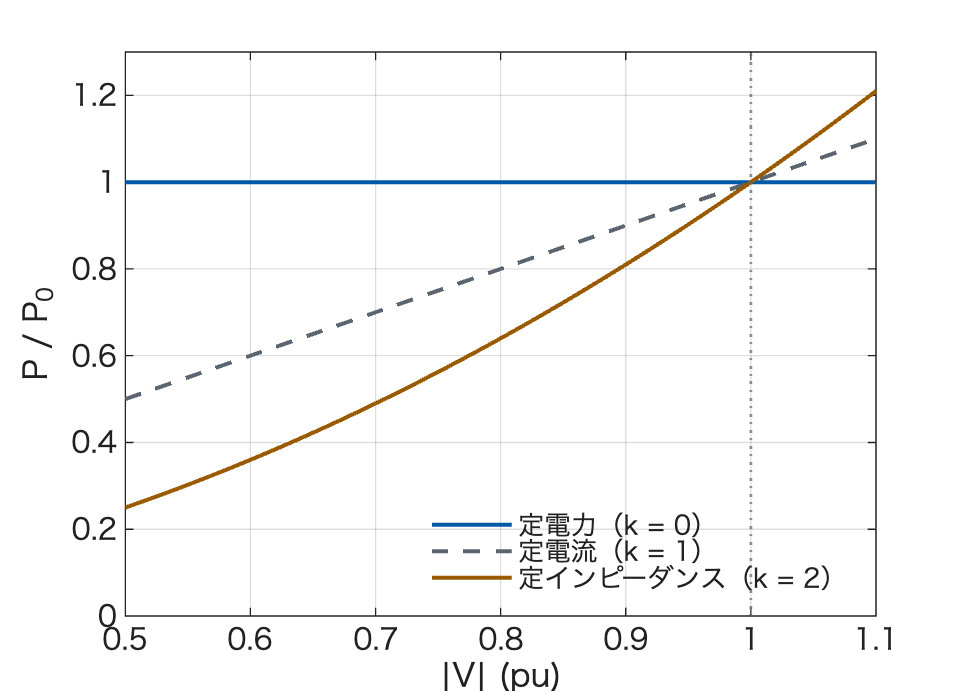

rv_V = linspace(0.5, 1.1, 121)';   % [pu] 母線電圧
rr_k = [0, 1, 2];
sr_load = ["定電力（k = 0）", "定電流（k = 1）", "定インピーダンス（k = 2）"];
rm_loadColor = [sct_color.rr_brand; sct_color.rr_muted; sct_color.rr_c3];
sr_style = ["-", "--", "-"];
figure(Position=[100, 100, 560, 400]);
ax = axes(XLim=[0.5, 1.1], YLim=[0, 1.3], XGrid="on", YGrid="on", Box="on");
hold(ax, "on");
for i_k = 1:numel(rr_k)
    plot(ax, rv_V, rv_V .^ rr_k(i_k), sr_style(i_k), Color=rm_loadColor(i_k, :), LineWidth=1.5, ...
        DisplayName=sr_load(i_k));
end
xline(ax, 1, ":", Color=sct_color.rr_muted, LineWidth=1, HandleVisibility="off");
xlabel(ax, "|V| (pu)");
ylabel(ax, "P / P_0");
legend(ax, Location="southeast", Box="off");

運転点の電圧では 3 つとも同じ電力を消費し、電圧が下がったときに違いが出ます。電圧が 0.8 pu に下がると、定インピーダンス負荷の消費電力は $0.8^2 = 0.64$ 倍に減りますが、定電力負荷は変わりません。定電力負荷は電圧が下がるとそのぶん多くの電流を流し（$I = P/V$）、それが送電線での電圧の低下をさらに大きくします。電圧崩壊の原因の 1 つで、系統にとって最も厳しい負荷です。逆に定インピーダンス負荷は、電圧が下がると消費を減らして系統を助ける向きに働きます。

GUILDA の負荷モデルは 4 つです。3 つの型にそれぞれ対応する `load-impedance`（定インピーダンス、タグ `LRX`）、`load-current`（定電流、タグ `LI`）、`load-power`（定電力、タグ `LPQ`）と、3 つの型を係数 `kPZ`・`kPI`・`kPP`（無効電力は `kQZ`・`kQI`・`kQP`）で 1 つの機器の中で混ぜる `load-ZIP`（タグ `LZIP`）です。`load-ZIP` の既定は、有効電力が定電流（`kPI = 1`）、無効電力が定インピーダンス（`kQZ = 1`）で、電圧が 0.7 pu（`VswitchP`・`VswitchI`）より下がると、定電流と定電力の部分は定インピーダンスに切り替わります。母線 5 の定インピーダンス負荷を、定電力負荷に置き換えます。

net9.get_element("B005").replace_component("B005LRX1", "load-power");
tab_bus5 = net9.get_element_table(Owner="B005");
tab_bus5(:, ["Key", "Class"])

ans = 1×2 table
                    Key                 Class         
                ____________    ______________________

    B005LPQ1    "load-power"    "component.load.power"


潮流計算では、どの負荷も決まった $P$ と $Q$ として扱うので、置き換えても潮流計算の結果は変わりません。負荷の型が効いてくるのは電圧が動くとき、つまり時間シミュレーションや近似線形化のときです。

**注意**: 混ざった負荷は、`load-ZIP` 1 つで表せます。1 つの母線には複数の機器をつなげるので、母線の負荷を型の違う部分に分け、`load-impedance`・`load-current`・`load-power` のうち必要なものを `add_component` で同じ母線に加えても表せます（部分ごとに解列したいときなど）。運転点では各部分の電力の和が母線の負荷になり、電圧が変わると、各部分がそれぞれの型に従って変わります。

## 8. 制御器：ローカルとグローバル

発電機だけでは、電圧や周波数を一定に保てません。制御器が状態を測り、発電機の入力を調整します。GUILDA では、制御器を「何を観測し、何を動かすか」で 2 つに分けます。**ローカル制御器**は 1 つの機器に属し、その機器（とその母線）を観測して、その機器の入力を動かします。**グローバル制御器**は系統全体に属し、複数の機器を観測して、複数の機器の入力をまとめて動かします。

- **AVR**（自動電圧調整器）: 界磁電圧 `Vfield` を調整して、端子電圧を設定値に保ちます（`avr-DC1`、`avr-ST1`）。

- **PSS**（系統安定化装置）: 速さのずれ $\omega$ を見て AVR に信号を加え、回転子の揺れを早く収めます（`pss-PSS1`）。

- **ガバナ**（調速機）: 回転の速さが変わると機械入力 `Pmech` を変え、需要の変化を数秒のうちに分担します（`gov-LPT1` など）。

- **AGC**（自動発電制御、グローバル制御器）: 周波数のずれを積分し、その補正を複数の発電機に割り振って、周波数を定格の値に戻します（`agc-PI`）。

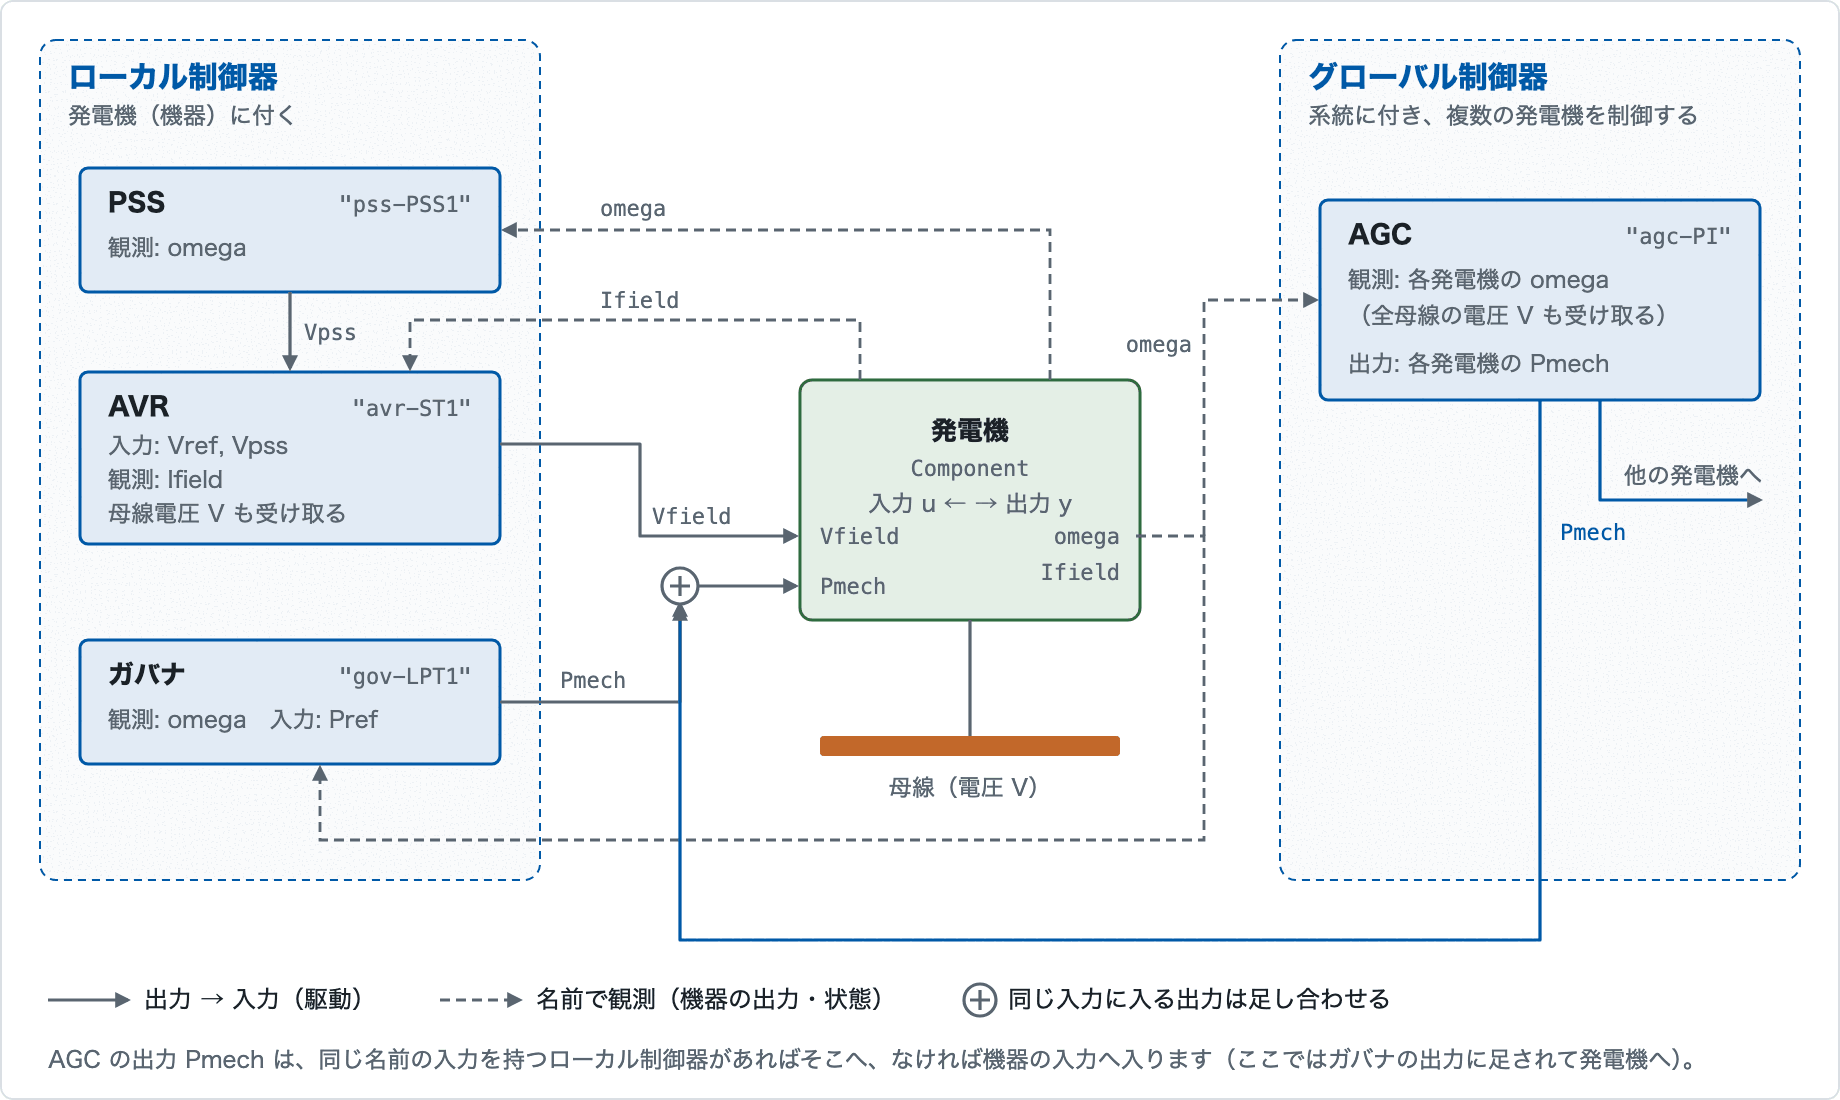

図は一例です（この節で付ける AVR は `avr-DC1` です）。実線は制御器の出力が機器の入力を動かすこと、破線は名前で機器の出力や状態を観測することを表します（PSS とガバナは発電機の `omega` を、`avr-ST1` は界磁電流 `Ifield` を観測します）。ガバナの `Pmech` と AGC の `Pmech` のように、同じ入力に入る出力は足し合わされます。母線 1 の発電機に付いている制御器を見ます。

gen1.disp_tree();


 B001SG1 @component.generator.one_axis
   ┣━━ B001SG1CA1 @controller.avr.AVR_ST1
   ┃     ┗━━ B001SG1CP2 @controller.pss.PSS1
   ┗━━ B001SG1CG1 @controller.governor.Static




AVR（タグの `CA`、`AVR_ST1`）が付き、その下に PSS（`CP`）が付いています。PSS は AVR に信号を加えるので、AVR の下にあります。ガバナ（`CG`）は入力を一定に保つ静的なものです。`add_local_controller` で AVR を `"avr-DC1"` に、ガバナを `"gov-LPT1"` に替えたあと、PSS を取り外します。パラメータを既定値から変えるときは `parameter` で指定します（ここでは AVR のゲイン `kap` を 50 にします）。

gen1.add_local_controller("avr-DC1", parameter=struct(kap=50));

gen1.add_local_controller("gov-LPT1");
gen1.remove_local_controller("B001SG1CP2");
gen1.disp_tree();


 B001SG1 @component.generator.one_axis
   ┣━━ B001SG1CA3 @controller.avr.AVR_DC1
   ┗━━ B001SG1CG4 @controller.governor.IEEJ_LPT1




警告のとおり、新しい AVR は前の AVR と置き換わりました。ガバナも静的なものから `IEEJ_LPT1` に替わり、AVR と並んで付いています。AVR は界磁電圧を、ガバナは機械入力を動かすので、1 台の発電機に両方を付けられます。最後に、付け替えた系統の平衡点を求め直します。

net9.initialize();
net9.disp_tree();


 PowerNetwork @network.IEEE9bus
   ┣━━ B001 @Bus
   ┃     ┗━━ B001SG1 @component.generator.one_axis
   ┃          ┣━━ B001SG1CA3 @controller.avr.AVR_DC1
   ┃          ┗━━ B001SG1CG4 @controller.governor.IEEJ_LPT1
   ┣━━ B002 @Bus
   ┃     ┗━━ B002SG1 @component.generator.two_axis
   ┃          ┣━━ B002SG1CA1 @controller.avr.AVR_ST1
   ┃          ┃     ┗━━ B002SG1CP2 @controller.pss.PSS1
   ┃          ┗━━ B002SG1CG1 <a hr

母線 2 は AVR と PSS を引き継いだ 2 軸モデル、母線 3 は静的な制御器だけの古典モデル、母線 5 は定電力負荷になり、母線 1 の発電機には AVR（DC1）とガバナが付いています。`initialize` が警告なしで終われば、この系統で解析を始められます。

**注意**: 機器や制御器を変えると平衡点は古くなり、解析の前に `net.initialize()` が必要になります。ローカル制御器の種類と Key は `GUILDA.dictionary("LocalController")` で一覧できます。グローバル制御器は `net.add_global_controller` で系統に加えます（Part 8 で扱います）。

## 9. 同梱のベンチマーク系統

大きな系統をデータから組み立てるのは手間がかかり、また同じ系統を使わなければ結果を比べられません。そこで研究では、共通のベンチマーク系統が使われます。GUILDA に同梱された系統を読み込み、母線の数を数えて並べます（読み込みの表示は `evalc` で隠します）。

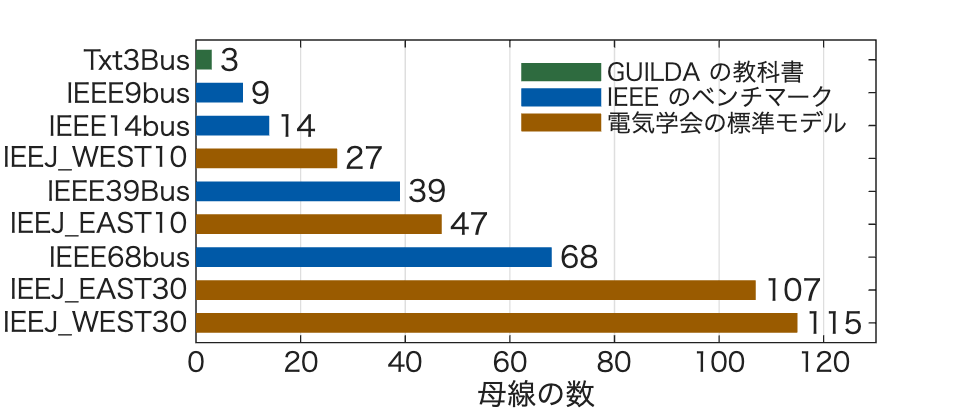

sr_net = ["Txt3Bus", "IEEE9bus", "IEEE14bus", "IEEE39Bus", "IEEE68bus", ...
    "IEEJ_WEST10", "IEEJ_EAST10", "IEEJ_EAST30", "IEEJ_WEST30"];
iv_group = [1, 2, 2, 2, 2, 3, 3, 3, 3];   % 1 教科書、2 IEEE、3 電気学会
rr_nbus = zeros(1, numel(sr_net));
for i_net = 1:numel(sr_net)
    [~, netB] = evalc("network." + sr_net(i_net) + "()");
    rr_nbus(i_net) = numel(netB.a_Bus);
end
[rr_nbus, iv_order] = sort(rr_nbus);
sr_net = sr_net(iv_order);
iv_group = iv_group(iv_order);

sr_group = ["GUILDA の教科書", "IEEE のベンチマーク", "電気学会の標準モデル"];
rm_groupColor = [sct_color.rr_c2; sct_color.rr_brand; sct_color.rr_c3];
figure(Position=[100, 100, 900, 380]);
ax = axes(YDir="reverse", YTick=1:numel(sr_net), YTickLabel=strrep(sr_net, "_", "\_"), ...
    XLim=[0, 130], YLim=[0.4, numel(sr_net) + 0.6], XGrid="on", Box="on");
hold(ax, "on");
for i_group = 1:3
    lv_in = iv_group == i_group;
    barh(ax, find(lv_in), rr_nbus(lv_in), 0.6, FaceColor=rm_groupColor(i_group, :), ...
        EdgeColor="none", DisplayName=sr_group(i_group));
end
text(ax, rr_nbus + 1.5, 1:numel(sr_net), string(rr_nbus), VerticalAlignment="middle");
xlabel(ax, "母線の数");
legend(ax, Location="northeast", Box="off");

3 母線から 115 母線までの系統があります。小さな系統は仕組みを理解するのに、大きな系統は実際の規模の系統のふるまいを見るのに向いています。

- `Txt3Bus`: GUILDA の基になった教科書の 3 母線の例です。

- `IEEE9bus`: WSCC の 3 機系統です。すべての母線を追える小ささで、この講義の多くの Part で使います。

- `IEEE14bus`: 潮流計算の代表的な試験系統です。

- `IEEE39Bus`: ニューイングランドの 10 機系統です。

- `IEEE68bus`: ニューイングランドとニューヨークの 16 機系統で、地域間の振動を調べる標準の系統です。

- `IEEJ_EAST10/30`、`IEEJ_WEST10/30`: 電気学会の標準モデルです。EAST は 50 Hz、WEST は長く延びた 60 Hz の系統で、昼のピーク（10）と夜（30）の 2 つの断面があります。

同梱の系統も普通の系統と同じで、この Part で行ったように、機器や制御器を加えたり、置き換えたり、取り除いたりできます。

## まとめ

- 電力系統のモデルは、母線・ブランチ・機器・制御器の 4 種類の部品で組み立てます。GUILDA では `add_bus`・`add_branch`・`add_component` で加え、Slack 母線を 1 つ決めます。

- 単位法では各量を基準値で割り、どの電圧階級でも正常な値が 1 の近くになります。$Z_\mathrm{base} = V_\mathrm{base}^2/S_\mathrm{base}$ で実際の単位に戻せます。

- 送電線は直列インピーダンスと対地静電容量の π 型回路、変圧器は漏れリアクタンスとタップで表します。ブランチの 2×2 の行列を足し込むと母線アドミタンス行列になり、$I = YV$ が注入電流と母線電圧を結びます。$Y$ は疎行列です。

- 母線は $|V|$・$\theta$・$P$・$Q$ のうち 2 つを決めます。Slack 母線は $|V|$ と $\theta$、PV 母線は $P$ と $|V|$、PQ 母線は $P$ と $Q$ で、未知数と式の数がそろいます。

- 発電機は動揺方程式 $M\,\mathrm{d}\omega/\mathrm{d}t = P_\mathrm{m} - P_\mathrm{e} - D\omega$ に従い、モデルにはドループ・古典から Park までの段階があります。

- 負荷は電圧によって電力がどう変わるかで型が分かれ、定電力負荷は系統にとって最も厳しい負荷です。ローカル制御器（AVR・PSS・ガバナ）は 1 台の発電機に、グローバル制御器（AGC）は複数の発電機にまとめて働きます。

**次の Part**: Part 2「潮流計算」では、組み立てた系統の電力方程式を解き、母線の電圧とブランチを流れる電力を求めます。

[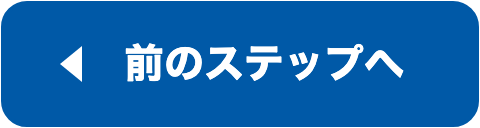](matlab:open('Part0_Introduction.mlx'))　　[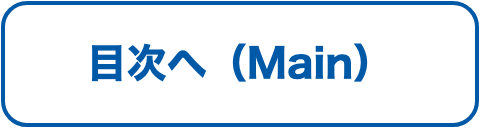](matlab:open('Main.mlx'))　　[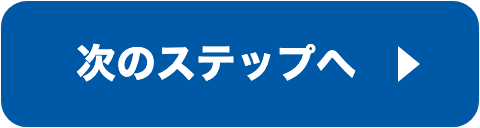](matlab:open('Part2_PowerFlow.mlx'))